Mini-Project 2  >>  Problem 2

clear, clc, close all

res = 500; % resolusion
train_sample = 100; % number of random train samples
test_sample = 50; % number of random test samples

U = [-.5 .3 ; -4 2.5];
x1 = linspace(U(1,1),U(1,2),res);
x2 = linspace(U(2,1),U(2,2),res);
%%
MlGLcg = 1.1026;
Bm = 2.3616;
Fc = 1.1949;
J = 0.4494;
f = @(x1,x2) - MlGLcg * sin(x1) - Bm * x2 - Fc * sign(x2) / J;
%%
output = f(x1,x2);
V = linspace(min(output), max(output), res);

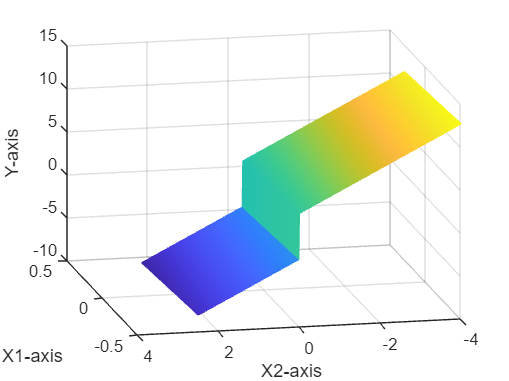

[X1,X2] = meshgrid(x1,x2);
mesh(X1,X2,f(X1,X2))
xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
view([-102.3 19.5])
hold on

% view([-90 0])

## a

rnd1 = x1(randperm(res));
rnd2 = x2(randperm(res));

x1tr = rnd1(1:train_sample);
x2tr = rnd2(1:train_sample);

x1te = rnd1(train_sample+1:train_sample+1+test_sample);
x2te = rnd2(train_sample+1:train_sample+1+test_sample);

ytr = f(x1tr,x2tr);%f([x1tr;x2tr]);
yte = f(x1te,x2te);%f([x1te;x2te]);

## a - plot

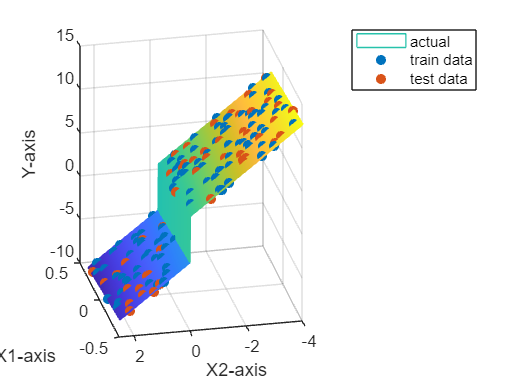

scatter3(x1tr,x2tr,f(x1tr,x2tr),'filled')
hold on
scatter3(x1te,x2te,f(x1te,x2te),'filled')
view([-102.3 19.5])
legend('actual','train data','test data')
xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
hold off

## Number of MFs

max_require_error = 0.1; 
syms x11 x22 h1 h2 e h
D1x1 = diff(f(x11,x22),x11)

$$D1x1 = -\frac{5513\,\cos\left(x_{11}\right)}{5000}$$

D1x2 = diff(f(x11,x22),x22)

$$D1x2 = -\frac{569\,\delta (x_{22})}{107}-\frac{1476}{625}$$

D2x1 = diff(f(x11,x22),x11,2)

$$D2x1 = \frac{5513\,\sin\left(x_{11}\right)}{5000}$$

D2x2 = diff(f(x11,x22),x22,2)

$$D2x2 = -\frac{569\,\delta^{\prime }(x_{22})}{107}$$

infnorm1x1 = norm(subs(D1x1,x1),'inf')

$$infnorm1x1 = \frac{5513\,\cos\left(\frac{902524975425}{4503599627370496}\right)}{5000}$$

infnorm1x2 = norm(subs(D1x2,x2),'inf')

$$infnorm1x2 = \frac{1476}{625}$$

infnorm2x1 = norm(subs(D2x1,x1),'inf')

$$infnorm2x1 = \frac{5513\,\sin\left(\frac{1}{2}\right)}{5000}$$

infnorm2x2 = norm(subs(D2x2,x2),'inf')

$$infnorm2x2 = 0$$

h1=1/8*h2

$$h1 = \frac{h_{2}}{8}$$

h11 = double(solve(subs(infnorm1x1 * h2/8 + infnorm1x2 * h2 == e, e, max_require_error)))

h11 = 0.0400

h22 = double(solve(subs(1/8 * (infnorm2x1 * h1^2 + infnorm2x2 * h2^2) == e, e, max_require_error)));
h22 = h22(h22>0)

h22 = 9.8416

n_mf1_x1 = round(abs(U(2)-U(1))/h11 + 1);
n_mf1_x2 = n_mf1_x1*8;
n_mf2_x1 = round(abs(U(2)-U(1))/h22 + 1);
n_mf2_x2 = n_mf2_x1*8;

approximate1 = [n_mf1_x1 n_mf1_x2]

approximate1 =     88   704


approximate2 = [n_mf2_x1 n_mf2_x2]

approximate2 =      1     8


test_input = [x1te;x2te];
test_output = f(test_input(1,:),test_input(2,:));
n_mfx1 =3;
n_mfx2 =24;
n_mfy = 20;
n_mfx = [n_mfx1,n_mfx2];
xbars{1} = linspace(x1(1), x1(end), n_mfx1);% -0.1;
xbars{2} = linspace(x2(1), x2(end), n_mfx2);
ybars = linspace(min(output), max(output), n_mfy);
 

% MFs according to train data - complete - consistent
% triangular a=x(i-1), b=x(i), c=x(i+1)

% xbars = sort(xtr);
% n_mf = numel(xtr);
% ybars = sort(ytr);

Create MF

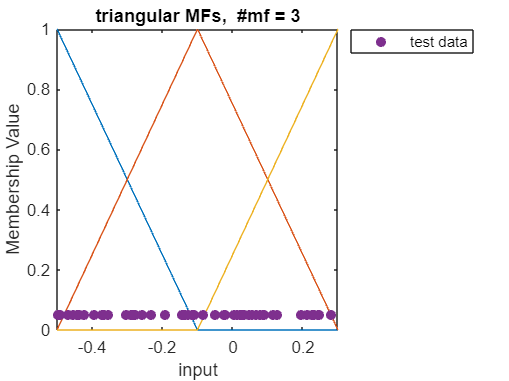

A1 = create_mfx(n_mfx1,U(1,:),xbars{1},x1,test_input(1,:));

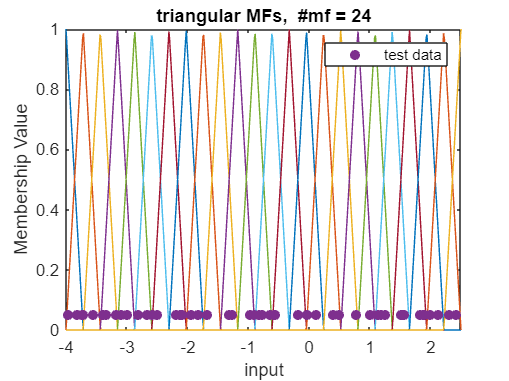

A2 = create_mfx(n_mfx2,U(2,:),xbars{2},x2,test_input(2,:));

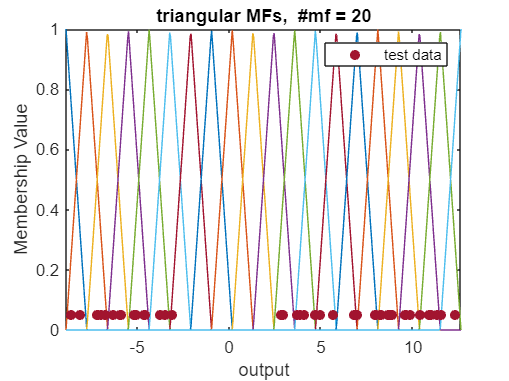

B = create_mfy(n_mfy,V,ybars,test_output);

METHOD 1 : chapter 10,11

mse = 0.0429

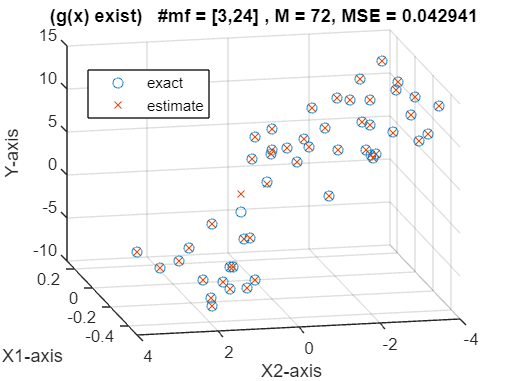

ch1011(f,n_mfx,xbars,test_input,test_output,{A1,A2})

METHOD 2: chapter 12

fix_rule = false;
[MFs,rule] = ch12_train(train_sample,{A1,A2,B},[x1tr;x2tr],ytr,fix_rule);
rule11 = rule;

mse = 0.2781

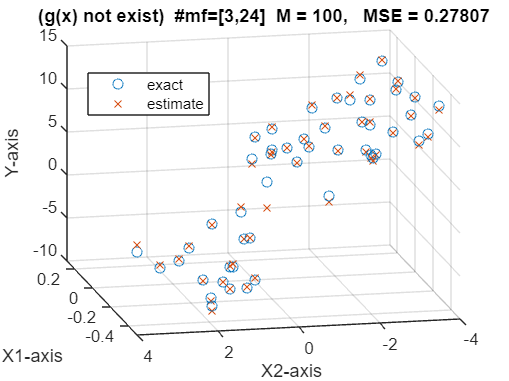

yest_rul = ch12_test(test_input,test_output,MFs,rule,ybars,[n_mfx1,n_mfx2]);

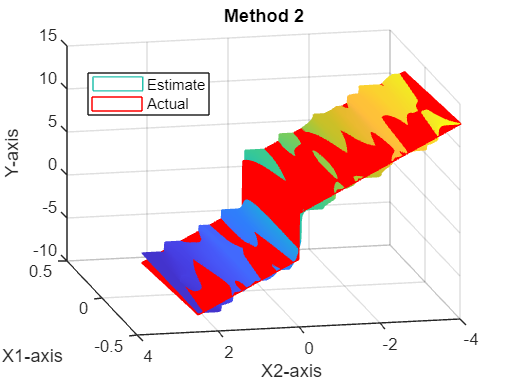

for i = 1:500
yest_rul_3d(i,:) = FS.COAdefuzz([X1(i,:);X2(i,:)], MFs, ybars(rule(:,end)));
end
% mesh
figure(2)
mesh(X1(2:end,2:end),X2(2:end,2:end),yest_rul_3d(2:end,2:end))
xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
view([-102.3 19.5])
hold on 
mesh(X1,X2,f(X1,X2),'EdgeColor','r')
legend('Estimate','Actual')
legend("Position", [0.20514,0.70807,0.175,0.092942])
title('Method 2')
% view([-90 0])
hold off

mse = 0.1959

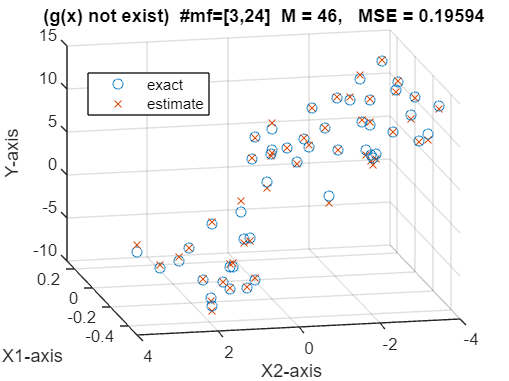

fix_rule = true;
[MFs,rule] = ch12_train(train_sample,{A1,A2,B},[x1tr;x2tr],ytr,fix_rule);
rule22 = rule;
yest_fixrul = ch12_test(test_input,test_output,MFs,rule,ybars,[n_mfx1,n_mfx2]);

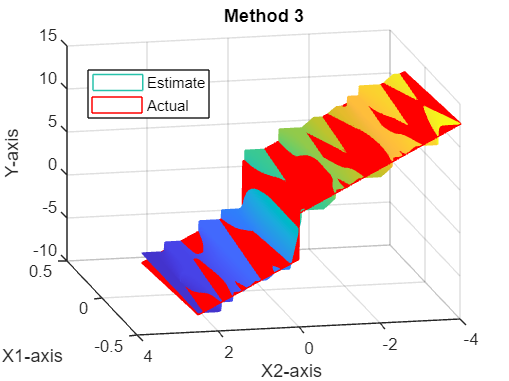

for i = 1:500
yest_fixrul_3d(i,:) = FS.COAdefuzz([X1(i,:);X2(i,:)], MFs, ybars(rule(:,end)));
end
% mesh
figure(2)
mesh(X1(2:end,2:end),X2(2:end,2:end),yest_fixrul_3d(2:end,2:end))
xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
view([-102.3 19.5])
hold on
mesh(X1,X2,f(X1,X2),'EdgeColor','r')
legend('Estimate','Actual')
legend("Position", [0.20514,0.70807,0.175,0.092942])
title('Method 3')
% view([-90 0])
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function y = f(x1,x2)
% MlGLcg = 1.1026;
% Bm = 2.3616;
% Fc = 1.1949;
% J = 0.4494;
% y = - MlGLcg * sin(x1) - Bm * x2 - Fc * sign(x2) / J;
% end

function ch1011(g,N,xbars,test_input,test_output,A)
%% Design Fuzzy System : Method 1 (ch10,11 Wang)

% Step 1: construct MFs : normal - complete - consistent - psudoTrapMF
    % xbars constructed
% Step 2: construct M and ybars
    % M = N1 * N2
    % ybars_exact = g(xbars);
% Step 3: construct fuzzy system {f(x)}
    % product - infrence engine
    % singletin - fuzzifier
    % center average - defuzzifier
    % f(x) = sumN1 sumN2 ybar(i1,i2) prod(muA) / sumN1 sumN2  prod(muA)

p = zeros(1,size(test_input,2));
q = zeros(1,size(test_input,2));
for i1 = 1:N(1)
    for i2 = 1:N(2)
        ybar_i1i2 = g(xbars{1}(i1),xbars{2}(i2));
        muA = A{1}(i1).membership(test_input(1,:)) .* A{2}(i2).membership(test_input(2,:));
        p = p + ybar_i1i2 * muA;
        q = q + muA;
    end
end
yest_exact = p./q;

% plot
% ybar = g(xbars);
% stem(ybar,ones(1,numel(ybar)))
% xlim([-1.2,0.1]), ylim([0,1.1]), xlabel('output'), ylabel('Membership Value'), title('singleton MFs'), hold off
% plot
mse = sum((yest_exact-test_output).^2)/numel(test_input)
% plot3(x(1,:),x(2,:),g(x)
% hold on
scatter3(test_input(1,:),test_input(2,:),test_output), hold on
scatter3(test_input(1,:),test_input(2,:),yest_exact,'x')
title("(g(x) exist)   #mf = ["+N(1)+","+N(2)+"] , M = "+prod(N)+", MSE = " + mse)
xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
legend('exact','estimate')
legend("Position", [0.20514,0.70807,0.175,0.092942])
view([-102.3 19.5])
% view([-90 0])
hold off
end

function [MFs,rule] = ch12_train(train_sample,MF,xtr,ytr,fix_rule)
% find rules
[rule, star] = findRules(train_sample,MF,xtr,ytr);
if fix_rule
    % find useful rules
    rule = useful_Rules(rule,star);
end
% create mega MFs matrix
MFs = RuleMf(rule,MF);
% Fuzzy System with COA-defuzzifier
% yest = FS.COAdefuzz(xte, MFs, ybars(rule(:,end)));
% MSE
% mse = sum((yest-yte).^2)/numel(xte)

% scatter
% scatter3(xte(1,:),xte(2,:),yte), hold on
% scatter3(xte(1,:),xte(2,:),yest,'x')
% title("(g(x) not exist)    M = "+size(rule,1)+", MSE = " + mse)
% hold off
end

function yest = ch12_test(xte,yte,MFs,rule,ybars,N)
    yest = FS.COAdefuzz(xte, MFs, ybars(rule(:,end)));
    mse = sum((yest-yte).^2)/numel(yte)
    % plot
    scatter3(xte(1,:),xte(2,:),yte), hold on
    scatter3(xte(1,:),xte(2,:),yest,'x')
    title("(g(x) not exist)  #mf=["+N(1)+","+N(2)+"]  M = "+size(rule,1)+",   MSE = " + mse)
    xlabel('X1-axis'), ylabel('X2-axis'), zlabel('Y-axis')
    legend('exact','estimate')
    legend("Position", [0.20514,0.70807,0.175,0.092942])
    view([-102.3 19.5])
    % view([-90 0])
    hold off
end

function [rule, star_value] = findRules(train_sample,MF,xtr,ytr)
% Step 1 : find must active MF for each train data (A* and B*)
% Step 2 : create rules
M = train_sample;
for l = 1:M
    for dim = 1:size(xtr,1)
        for i = 1:numel(MF{dim})
            memberX(i,dim) = MF{dim}(i).membership(xtr(dim,l));
        end
    end
    for i = 1:numel(MF{end})
        memberY(i) = MF{end}(i).membership(ytr(l));
    end
    % Step 1
    [starXvalue(:,l),starX] = max(memberX);
    [starYvalue(l),starY] = max(memberY);
    % Step 2
    rule(l,:) = [starX, starY];    % IF x is A(starX) THEN y is B(starY)
end
star_value = [starXvalue;starYvalue]';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function A = create_mfx(n_mf,U,tbars,time,test_data)
% MF - equal width - complete - consistent - triangular - systematic
A(1:n_mf) = MF('tri'); % MF objects

for i = 1:n_mf
    if n_mf == 1
        a = U(1);
        b = tbars;
        c = U(end);
    else
        if i == 1
            a = U(1);
            b = tbars(1);
            c = tbars(2);
        elseif i == n_mf
            a = tbars(end-1);
            b = tbars(end);
            c = U(end);
        else
            a = tbars(i-1);
            b = tbars(i);
            c = tbars(i+1);
        end
    end
    A(i).par = {a,b,c};
    A1_mtx(i,:) = A(i).membership(time);
end

plot(time,A1_mtx)
title("triangular MFs,  #mf = "+n_mf), xlabel('input'), ylabel('Membership Value'), xlim([U(1),U(end)])
hold on
sc = scatter(test_data,ones(1,numel(test_data))*.05,"filled"); legend(sc,'test data')
hold off
end

function B = create_mfy(n_mf,V,ybars,test_data)
% MF(output) - equal width - complete - consistent - triangular
B(1:n_mf) = MF('tri'); % MF objects
for i = 1:n_mf
    if i == 1
        a = V(1);
        b = ybars(1);
        c = ybars(2);
    elseif i == n_mf
        a = ybars(end-1);
        b = ybars(end);
        c = V(end);
    else
        a = ybars(i-1);
        b = ybars(i);
        c = ybars(i+1);
    end
    B(i).par = {a,b,c};
    B_mtx(i,:) = B(i).membership(V);
end

plot(V,B_mtx)
title("triangular MFs,  #mf = "+n_mf), xlabel('output'), ylabel('Membership Value'), xlim([V(1),V(end)])
hold on
sc = scatter(test_data,ones(1,numel(test_data))*.05,"filled");
legend(sc,'test data')
hold off
end
